# DATA SERVER ENERGY CONSUMPTION DTASET

Víctor Asanza, Rebeca Estrada, Adrian Bazurto, Danny Torres

- `More examples: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `DataPort: `[https://dx.doi.org/10.21227/x6jw-m015](https://dx.doi.org/10.21227/x6jw-m015)

- Load Data, Sampling Rate=1sample/1seg

- Date = '2021-05-27 00:00:00' AND '2021-06-17 22:04:21'

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
%load('./data/dataset.mat');%Load table data
path = fullfile('./data/dataset.mat');
data=load(path);data=data.data;
dataNew=table2array(data(:,4:12));% Array Double
%csvwrite('data.csv',dataNew);%Save as .csv file

# Plot Raw Data (Dataset)

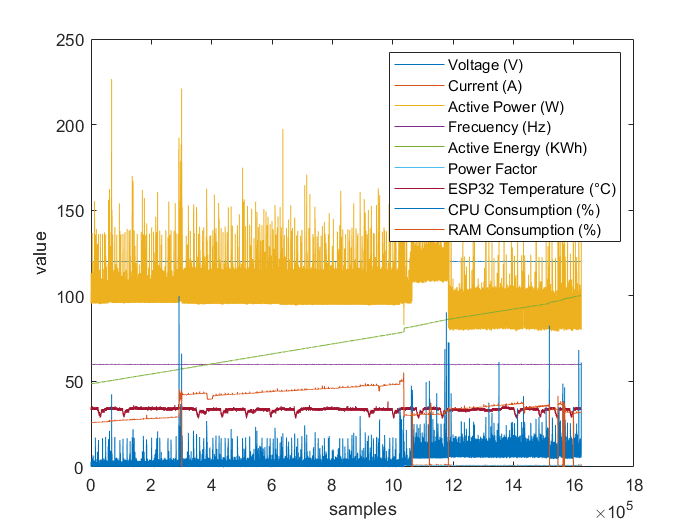

figure
plot(dataNew);xlabel('samples');ylabel('value');
legend('Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','RAM Consumption (%)');

# Statital Information Raw Data (Dataset)

xds_v = datastats(dataNew(:,1))%Voltage (V)

xds_v = struct with fields:
       num: 1625175
       max: 120.2000
       min: 119.4000
      mean: 120.0236
    median: 120
     range: 0.8000
       std: 0.0648


xds_C = datastats(dataNew(:,2))%Current (A)

xds_C = struct with fields:
       num: 1625175
       max: 1.9800
       min: 0.7000
      mean: 0.9240
    median: 0.9300
     range: 1.2800
       std: 0.0934


xds_AP = datastats(dataNew(:,3))%Active Power (W)

xds_AP = struct with fields:
       num: 1625175
       max: 226.6000
       min: 79.1000
      mean: 98.9189
    median: 96.6000
     range: 147.5000
       std: 9.3631


xds_F = datastats(dataNew(:,4))%Frecuency (Hz)

xds_F = struct with fields:
       num: 1625175
       max: 60.1000
       min: 59.7000
      mean: 59.9668
    median: 60
     range: 0.4000
       std: 0.0488


xds_AE = datastats(dataNew(:,5))%Active Energy (KWh)

xds_AE = struct with fields:
       num: 1625175
       max: 100.1200
       min: 48.5600
      mean: 73.3169
    median: 72.2300
     range: 51.5600
       std: 14.9472


xds_PF = datastats(dataNew(:,6))%Power Factor

xds_PF = struct with fields:
       num: 1625175
       max: 1
       min: 0.7300
      mean: 0.8946
    median: 0.8600
     range: 0.2700
       std: 0.0443


xds_T = datastats(dataNew(:,7))%ESP32 Temperature (°C)

xds_T = struct with fields:
       num: 1625175
       max: 38.3300
       min: 28.3300
      mean: 33.2923
    median: 33.8900
     range: 10
       std: 1.0580


xds_CPU = datastats(dataNew(:,8))%CPU Consumption (%)

xds_CPU = struct with fields:
       num: 1625175
       max: 99.8000
       min: 0
      mean: 3.8781
    median: 1.3000
     range: 99.8000
       std: 4.5249


xds_RAM = datastats(dataNew(:,9))%RAM Consumption (%)

xds_RAM = struct with fields:
       num: 1625175
       max: 55.2000
       min: 0
      mean: 37.6688
    median: 36.3500
     range: 55.2000
       std: 7.0824


# 1 - Preprocessing (Normalization)

DataNorm=[];
DataNorm=fNormalization(dataNew);

# Plot Normalization Data (Dataset)

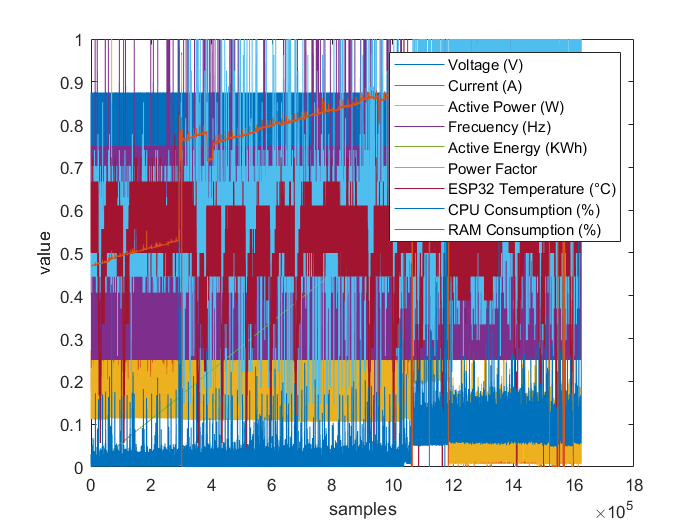

figure
plot(DataNorm);xlabel('samples');ylabel('value');
legend('Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','RAM Consumption (%)');

# 2 - Feature Extraction (rms by temporary window)

% Select only one TimeStep
% not enough data... TimeStep =2592000;% one month in second
%TimeStep =604800;% one week in second (only 2 weeks)
%TimeStep =86400;% one day in second (ok)
%TimeStep =3600;% one hour in second (ok)
TimeStep =60;% one minute in second
%TimeStep =1;% one second

DataFeatures=[];
for i = 1:size(DataNorm,2)%columnas
    Feature=[];
    for j = 1:TimeStep:size(DataNorm,1)-TimeStep%filas
        Feature=[Feature; rms(DataNorm(j:j+TimeStep,i))];
    end
    DataFeatures=[DataFeatures Feature];
end

% Feature 1: rms(Active Power (W))
xds_F1 = datastats(DataFeatures(:,1))

xds_F1 = struct with fields:
       num: 27086
       max: 0.8693
       min: 0.4401
      mean: 0.7819
    median: 0.7953
     range: 0.4292
       std: 0.0542


% Feature 2: rms(Active Energy (KWh))
xds_F2 = datastats(DataFeatures(:,2))

xds_F2 = struct with fields:
       num: 27086
       max: 0.5796
       min: 0.0797
      mean: 0.1780
    median: 0.1887
     range: 0.5000
       std: 0.0654


% Feature 3: rms(CPU Consumption (%))
xds_F3 = datastats(DataFeatures(:,3))

xds_F3 = struct with fields:
       num: 27086
       max: 0.5551
       min: 0.0922
      mean: 0.1386
    median: 0.1253
     range: 0.4630
       std: 0.0536


% Feature 4: rms(RAM Consumption (%))
xds_F4 = datastats(DataFeatures(:,4))

xds_F4 = struct with fields:
       num: 27086
       max: 0.7828
       min: 0.2772
      mean: 0.6762
    median: 0.6820
     range: 0.5055
       std: 0.0494


# 3 - Feature Selection

%corrplot(DataNorm)
R = corrcoef(DataFeatures)

R =     1.0000   -0.7712   -0.9131    0.2255   -0.0330   -0.0177    0.2061   -0.3039    0.0392
   -0.7712    1.0000    0.8662    0.0108   -0.4388   -0.5201   -0.0306   -0.2088    0.0872
   -0.9131    0.8662    1.0000    0.0064   -0.0161   -0.0243   -0.0489    0.2964   -0.0541
    0.2255    0.0108    0.0064    1.0000   -0.0134   -0.0117    0.0063   -0.0098   -0.0107
   -0.0330   -0.4388   -0.0161   -0.0134    1.0000    0.8466   -0.0452    0.7864    0.0403
   -0.0177   -0.5201   -0.0243   -0.0117    0.8466    1.0000   -0.0195    0.9216   -0.2858
    0.2061   -0.0306   -0.0489    0.0063   -0.0452   -0.0195    1.0000   -0.0266   -0.0923
   -0.3039   -0.2088    0.2964   -0.0098    0.7864    0.9216   -0.0266    1.0000   -0.2628
    0.0392    0.0872   -0.0541   -0.0107    0.0403   -0.2858   -0.0923   -0.2628    1.0000


%'Voltage (V)','Current (A)','Active Power (W)','Frecuency (Hz)','Active Energy (KWh)','Power Factor','ESP32 Temperature (°C)','CPU Consumption (%)','RAM Consumption (%)'
%Heat map
% Experimento: ESP32 Temperature
DataFeatures(:,7)=[];
% Based on corrcoef To delete: 
% PowerFactor -> alta correlacion con Active Energy (85%), entonces nos
% quedamos con Active Energy
% Voltage, current -> Alta correlacion con Active Power (91% y 86%),
% entonces nos quedfamos Active Power
DataFeatures(:,6)=[];DataFeatures(:,2)=[];DataFeatures(:,1)=[];
% Parametros electricos: Frecuency
DataFeatures(:,2)=[];
%Nos quedamos con estas variables: 'Active Power (W)','Active Energy (KWh)','CPU Consumption (%)','RAM Consumption (%)'

# 4 - Regression Learner (Input output Data)

training=0.85; %70 Training, 15% Validation, 15% Testing
testing=0.15;

input=[];output=[];
% inputs: Active Power (W),Active Energy (KWh),CPU Consumption (%),RAM Consumption (%)
input=DataFeatures(1:round(length(DataFeatures)*training)-1,:);
% output: Energía in the following time step
output=DataFeatures(1+1:round(length(DataFeatures)*training),2);
Samples=length(DataFeatures)*0.85-1

Samples = 2.3022e+04

# RMSE (Testing): 1 day   

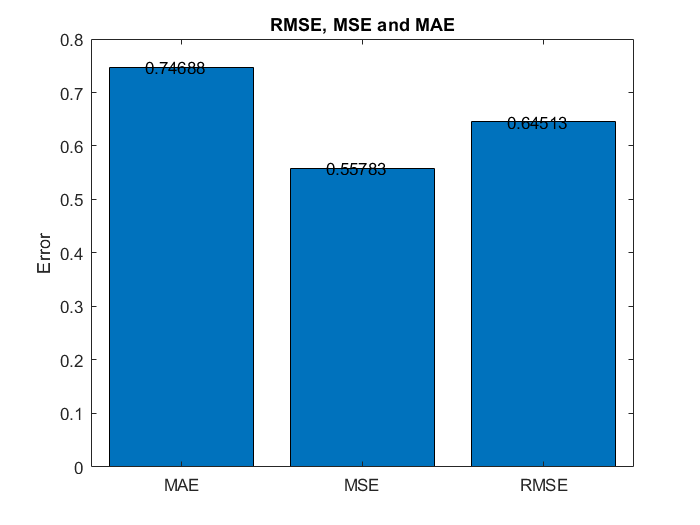

% inputs: Active Power (W),Active Energy (KWh),CPU Consumption (%),RAM Consumption (%)
input_testing=DataFeatures(round(length(DataFeatures)*training):length(DataFeatures)-1,:);
% output: Energía in the following time step
output_testing=DataFeatures(round(length(DataFeatures)*training)+1:length(DataFeatures),2);

% To make predictions on a new predictor column matrix, X, use:
% yfit = c.predictFcn(X)
% replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'.
% X must contain exactly 4 columns because this model was trained using 4 predictors.
% X must contain only predictor columns in exactly the same order and format as your training data.
% Do not include the response column or any columns you did not import into the app. 

trainedModel_1day=load('trainedModel_1day.mat');%Load Best Prediction Model by 1day
predictValue_1day=trainedModel_1day.trainedModel_1day.predictFcn(input_testing);
% Denormilize Data
DpredictValue_1day=fDenormalize(predictValue_1day,xds_AE.max,xds_AE.min);
Doutput_testing=fDenormalize(output_testing,xds_AE.max,xds_AE.min);
[rmse_1day,mse_1day,mae_1day]=fBar_RmseMseMae(DpredictValue_1day,Doutput_testing);

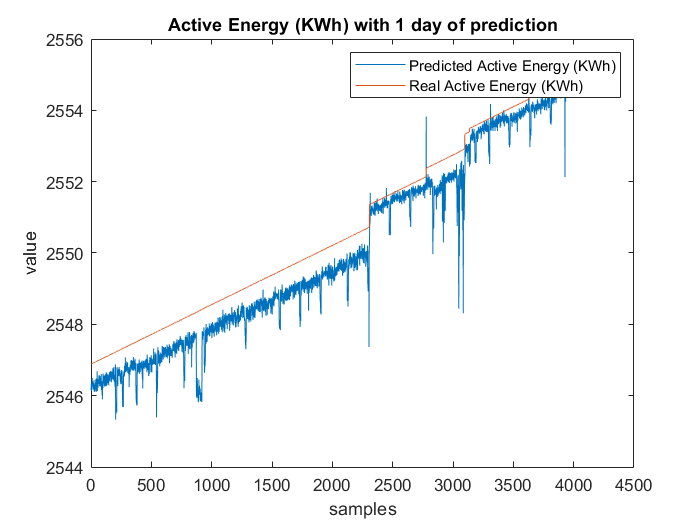

figure
plot([DpredictValue_1day,Doutput_testing]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 day of prediction');

# RMSE (Testing): 1 hour

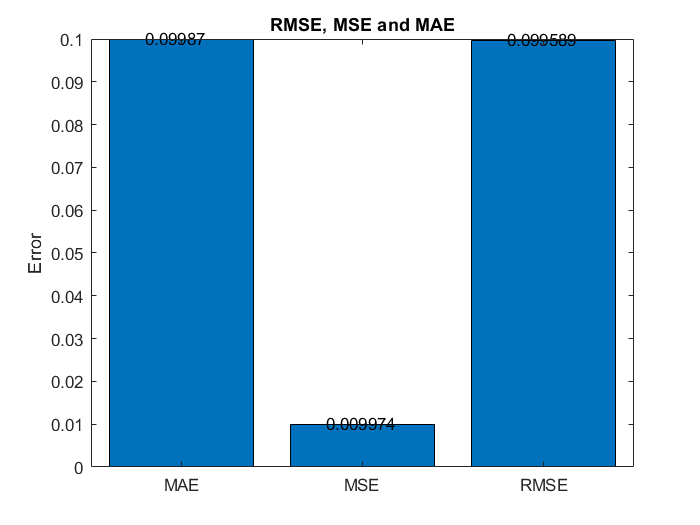

trainedModel_1hour=load('trainedModel_1hour.mat');%Load Best Prediction Model by 1hour
predictValue_1hour=trainedModel_1hour.trainedModel_1hour.predictFcn(input_testing);
% Denormilize Data
DpredictValue_1hour=fDenormalize(predictValue_1hour,xds_AE.max,xds_AE.min);
Doutput_testing=fDenormalize(output_testing,xds_AE.max,xds_AE.min);
[rmse_1hour,mse_1hour,mae_1hour]=fBar_RmseMseMae(DpredictValue_1hour,Doutput_testing);

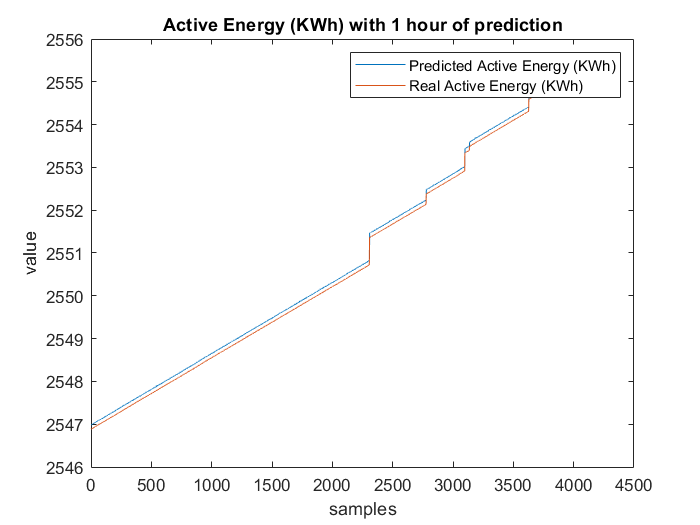

figure
plot([DpredictValue_1hour,Doutput_testing]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 hour of prediction');

# RMSE (Testing): minute

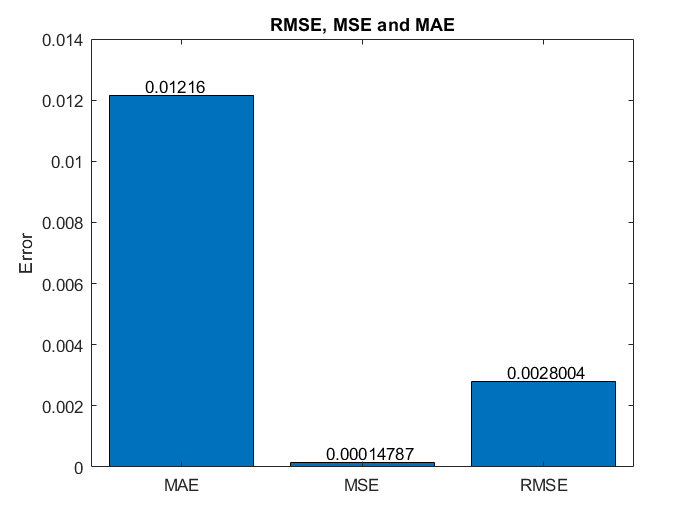

trainedModel_1min=load('trainedModel_1min.mat');%Load Best Prediction Model by 1min
predictValue_1min=trainedModel_1min.trainedModel_1min.predictFcn(input_testing);
% Denormilize Data
DpredictValue_1min=fDenormalize(predictValue_1min,xds_AE.max,xds_AE.min);
Doutput_testing=fDenormalize(output_testing,xds_AE.max,xds_AE.min);
[rmse_1min,mse_1min,mae_1min]=fBar_RmseMseMae(DpredictValue_1min,Doutput_testing);

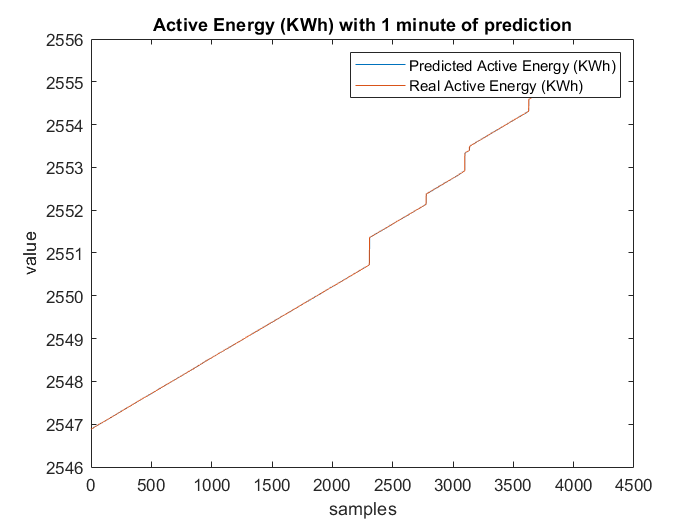

figure
plot([DpredictValue_1min,Doutput_testing]);xlabel('samples');ylabel('value');
legend('Predicted Active Energy (KWh)','Real Active Energy (KWh)');
title('Active Energy (KWh) with 1 minute of prediction');

# Summary RMSE (Testing): day, Hour and Min 

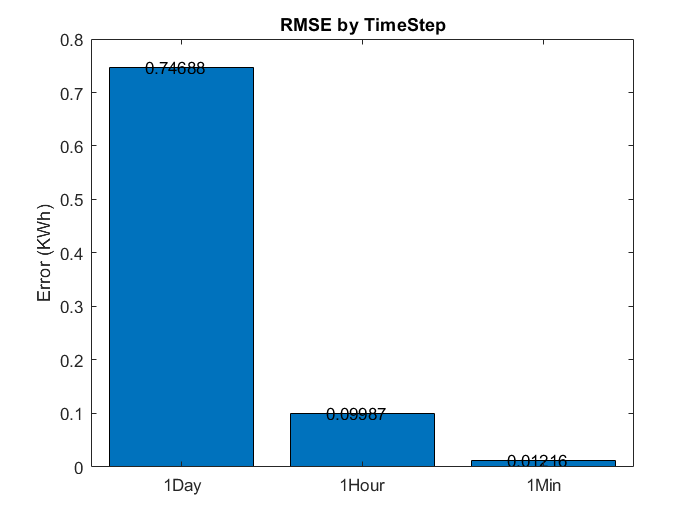

    c = categorical({'1Day','1Hour','1Min'});
    values = [rmse_1day rmse_1hour rmse_1min];
    figure;
    b=bar(c,values);
    ylabel('Error (KWh)')
    title('RMSE by TimeStep')
    xtips1 = b(1).XEndPoints - 0.2;
    ytips1 = b(1).YEndPoints + 0.0003;
    labels1 = string(b(1).YData);
    text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

# FutureWork

%New Testing adicional...
% NOTA: hacer una prueba sin CPU Consumption (%),RAM Consumption (%) y ver
% si ayudan a mejorar la prediccion...